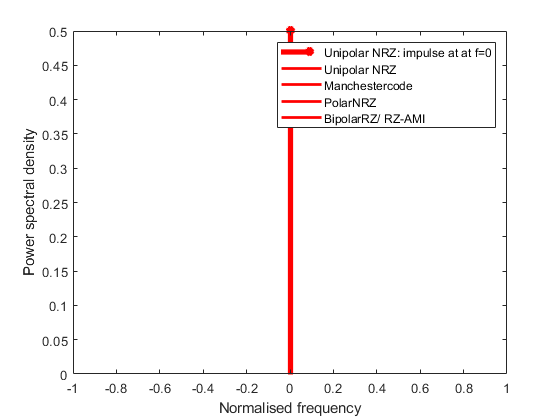

v=1; % voltage level of a bit
R=1; % Bitrate
T=1/R; % Bit period
f=0:0.001*R:2*R; % frequency vector in terms of bit rate
f= f+1e-10; % Otherwise, sin(0)/0 is undefined
% PSD curves are plotted for Bitrate=1bps and Pulse amplitude=1V

%Unipolar NRZ
s=((v^2*T/4).*(sin(pi.*f*T)./(pi.*f*T)).^2);
s(1)=s(1)+(v^2/4);% corresponds to an impulse function of weight v^2/4 at f=0 added to s(f) at
f=0;
ff=0;
stem(ff,s(1),'*r','LineWidth',4)% sketching an impulse at f=0
hold on;
plot(f,s,'-r','LineWidth',2);
hold on;

%Manchester code
s=(v.^2.*T).*((sin(pi.*f*T/2)./(pi.*f*T/2)).^2).*(sin(pi.*f*T/2).^2);
plot(f,s,'--g','LineWidth',2);
hold on;

%Polar NRZ
s=((v^2*T).*(sin(pi.*f*T)./(pi.*f*T)).^2);
plot(f,s,'--b','LineWidth',2);
hold on;

%Bipolar RZ
s=(v.^2.*T/4).*((sin(pi.*f*T/2)./(pi.*f*T/2)).^2).*(sin(pi.*f*T).^2);
plot(f,s,'--k','LineWidth',2);

legend('Unipolar NRZ: impulse at f=0','Unipolar NRZ', 'Manchestercode','PolarNRZ','BipolarRZ/ RZ-AMI');
xlabel('Normalised frequency');
ylabel('Power spectral density');